clear; close all; imtool close all; clc;rng('default')

## load retrained network to find a scrached nut

load('myalexnet')

## define dlnetowrk and layers used for showing activation map

classification layer should be removed to use in dlnetwork object

lgraph = layerGraph(convnet.Layers);
Outputlayer =  lgraph.Layers(end);
newlgraph = removeLayers(lgraph,lgraph.Layers(end).Name);
% To get gradient value, we use dlnetwork object.
net2 = dlnetwork(newlgraph);
softmaxlayer = 'prob' ; % softmaxlayer
activationlayer = 'relu5'; % layer you apply Grad-CAM

## Read test image and find nut

labeltbl = {'Bad';'Good'};
colortbl = [255 255 102; 73 6 248];
img = imread('ng1.png');% read image
hsv = rgb2hsv(img); % convert to HSV
th = otsuthresh(imhist(hsv(:,:,2))); % apply otsu method
bw = hsv(:,:,2) > th; % create a mask
bw = bwareaopen(~bw,5000); % morphorogy
bw = imclearborder(bw); %
stats = regionprops('table',bw,'BoundingBox'); % get bbox value
bbox = int16(stats.BoundingBox); %

## Clssify the cropped image

img2 = imcrop(img,bbox); % crop a ROI
img3 = imresize(img2,[227 227]); % resize
[class,score] = classify(convnet,img3); % predict

## apply Grad-CAM

img4 = dlarray(single(img3),'SSC');
% get value of output and gradient
[conv_output,gradients] = dlfeval(@Gradient_function,net2,img4,softmaxlayer,activationlayer,class);
% calculate gradcam
alpha = mean(gradients, [1 2]); % Global average pooling for getting neuron importance weights alpha
linearcombination = sum(conv_output .* alpha, 3); %
linearcombination = extractdata(linearcombination); % convert dlarray to single
gradcam = max(linearcombination,0); % apply relu function
gradcam = imresize(gradcam, [227 227], 'Method', 'bicubic'); % resize map to fit image

## convert gradcam to image data and show it with image

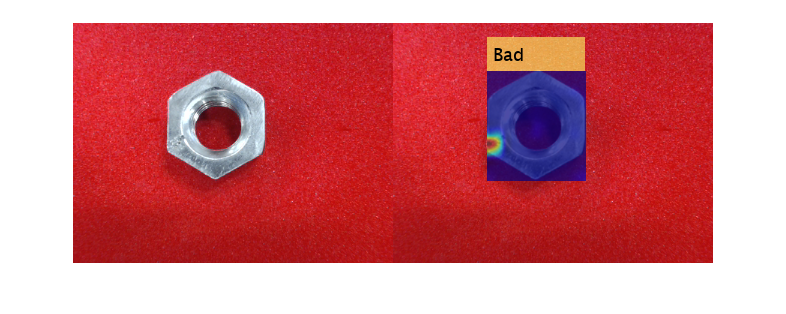

HeatMap = map2jpg(gradcam, [], 'jet'); % convert heatmap into image data
HeatMap = uint8((im2double(img3)*0.3+HeatMap*0.5)*255); % overrap images

[~,idx]=max(score);
out = insertObjectAnnotation(img, 'rectangle', bbox,... % add a Annotation
    labeltbl{idx}, 'FontSize', 18, 'Color', colortbl(idx,:)); %
out(bbox(2):bbox(2)+bbox(4),bbox(1):bbox(1)+bbox(3),:) = imresize(HeatMap,[bbox(4)+1 bbox(3)+1]);  %
out2 = [img out]; %
imshow(out2);shg

## function called from dlfeval

function [conv_output,gradients] = Gradient_function(net2,I2,softmaxlayer,activationlayer,class)
[scores,conv_output] = predict(net2, I2, 'Outputs', {softmaxlayer, activationlayer}); % get score and output at defiend layer.
loss = scores(class); %
gradients = dlgradient(loss,conv_output); % get gradient of loss with respect to conv_output
gradients = gradients / (sqrt(mean(gradients.^2,'all')) + 1e-5); % Normalization
end

## Function for creating heat map

function img = map2jpg(imgmap, range, colorMap)
imgmap = double(imgmap);
if(~exist('range', 'var') || isempty(range))
    range = [min(imgmap(:)) max(imgmap(:))];
end
heatmap_gray = mat2gray(imgmap, range);
heatmap_x = gray2ind(heatmap_gray, 256);
heatmap_x(isnan(imgmap)) = 0;

if(~exist('colorMap', 'var'))
    img = ind2rgb(heatmap_x, jet(256));
else
    img = ind2rgb(heatmap_x, eval([colorMap '(256)']));
end
end
%

*Copyright 2019 The MathWorks, Inc.*